# Logistic Growth Simulation 1

## Assumptions

I assume that the phosphate is either the limiting factor or directly correlated with it. I neglect any other limiting factor and I also neglect the chance of any parasitic activity occuring.

## Simulation

Organisms/critters will have three traits and one variable: rate of phosphate consumption, number of phosphates consumed before reproduction, number of phosphates consumed since last reproduction (variable), and drought resistance. The currency of this ecosystem will obviously be Phosphate and it will begin with an arbitrary amount.

%rng('default')
tic
Gen=20; % Number of Desired Generations

% Initializing variables
InitialPhosphate=100000;
AssayData=zeros(1,Gen); 
PopulationData=zeros(1,Gen); 
AppetiteData=zeros(1,Gen);
FertilityData=zeros(1,Gen);
ResistanceData=zeros(1,Gen);
Availability=1; % ratio of origional food supply left (to be changed)

% Generating a seed population
Population=[rand(1,400);rand(1,400).*2+4;zeros(1,400);rand(1,400)]; % appetite,fertility,stomach,resistance

Now that the initial conditions are set, the simulation can begin.

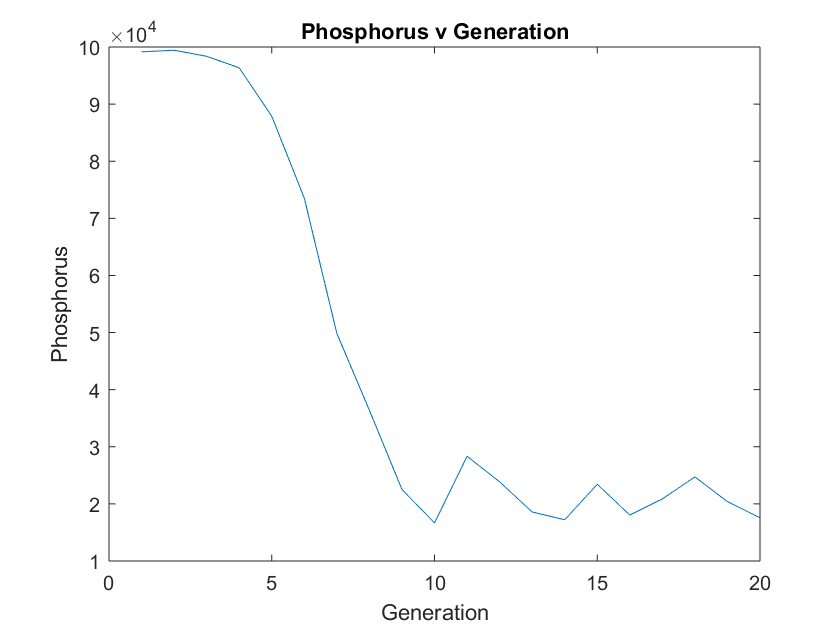

for Generation=1:1:Gen
    Phosphate=100000;
    for Time=0:1:10 % number of ticks per generation
        
        if Phosphate < 0 % to prevent weirdness from negative food supply
            Phosphate = 0 
            Availability = 0 
        end
        
        for n=1:1:length(Population(1,:))
            Phosphate=Phosphate-sum(Population(1,n)*Availability);  % eating part 1 of 2
            Population(3,n)=Population(3,n)+Population(1,n)*Availability;  % eating part 2 of 2
        end
        
        for i=1:1:length(Population(1,:))
            
            if Population(2,i) < Population(3,i) % test to see if critter is ready to reproduce
                Population(3,i)=Population(3,i)-Population(2,i);
                
                if rand(1) < .25 % 25 percent chance appetite is changed
                    if rand(1) < .5 % coin flip if it goes up or down
                        Var1=Population(1,i)+.1*Population(1,i); % goes up 10 percent
                    else
                        Var1=Population(1,i)-.1*Population(1,i); % goes down 10 percent
                    end
                else
                    Var1=0;
                end
             
                if rand(1) < .25 % 25 percent chance fertility is changed
                    if rand(1) < .5 % coin flip if it goes up or down
                        Var2=Population(2,i)+.1*Population(2,i); % goes up 10 percent
                    else
                        Var2=Population(2,i)-.1*Population(2,i); % goes down 10 percent
                    end
                else
                    Var2=0;
                end
                
                if rand(1) < .25 % 25 percent chance resistance is changed
                    if rand(1) < .5 % coin flip if it goes up or down
                        Var4=Population(4,i)+.1*Population(4,i); % goes up 10 percent
                    else
                        Var4=Population(4,i)-.1*Population(4,i); % goes down 10 percent
                    end
                else
                    Var4=0;
                end
                        
                Variation=[Var1, Var2, 0, Var4];
                Baby=Population(:,i)+Variation; % Baby=Parent+Variation
                Population=[Population Baby];
                
            end
        end
        
        Availability=Phosphate/InitialPhosphate; % update
        HitList=[]; % initialize variable
        for k=1:1:length(Population(1,:)) % analyse every member
            luck=rand(1); % can be dampened to increase survival rate
            if luck < Population(4,k)*Availability % test if it will live
                HitList=[HitList k]; % Mark it for death
            end
        end
        Population(:,HitList)=[]; % Darwin Award Ceremony 
        
    end
    
    % Data Collection Section
    AssayData(Generation)=[Phosphate]; 
    PopulationData(Generation)=[length(Population(1,:))];
    AppetiteData(Generation)=[sum(Population(1,:))/length(Population(1,:))];
    FertilityData(Generation)=[sum(Population(2,:))/length(Population(1,:))];
    ResistanceData(Generation)=[sum(Population(4,:))/length(Population(1,:))];
    %End of Data Collection Section
    
    luck2=rand(1,length(Population(1,:))); 
    HitList2=[];
    for m=1:1:length(Population(1,:))
        if luck2(m) < .9 % select 90 percent of population
            HitList2=[HitList2 m];
        end
    end
    Population(:,HitList2)=[];
end

plot([1:1:Gen],AssayData) 
title('Phosphorus v Generation')
xlabel('Generation')
ylabel('Phosphorus')

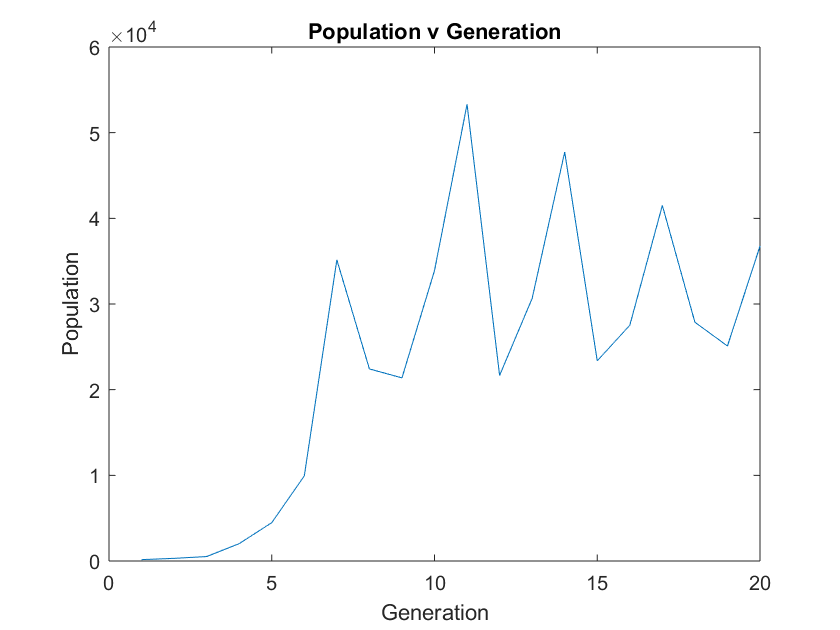

plot([1:1:Gen],PopulationData) 
title('Population v Generation')
xlabel('Generation')
ylabel('Population')

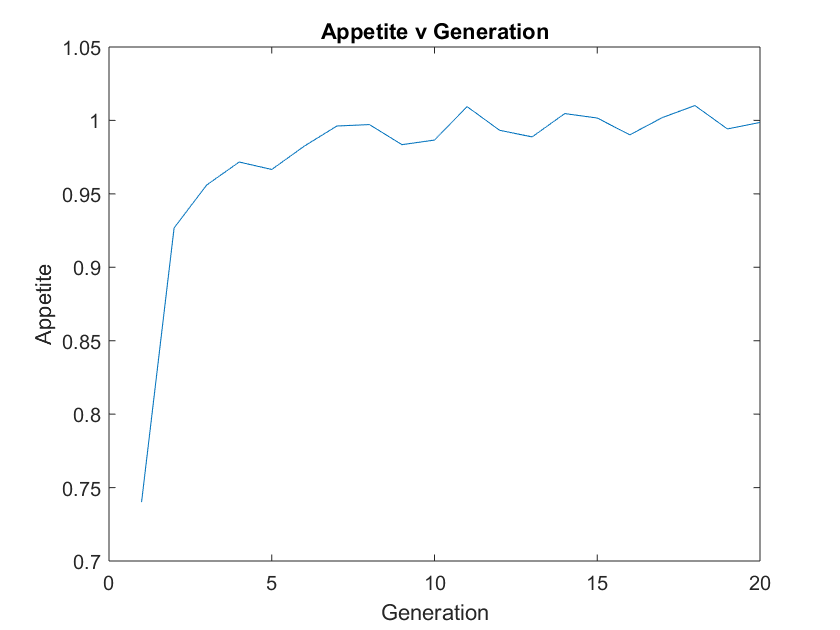

plot([1:1:Gen],AppetiteData) 
title('Appetite v Generation')
xlabel('Generation')
ylabel('Appetite')

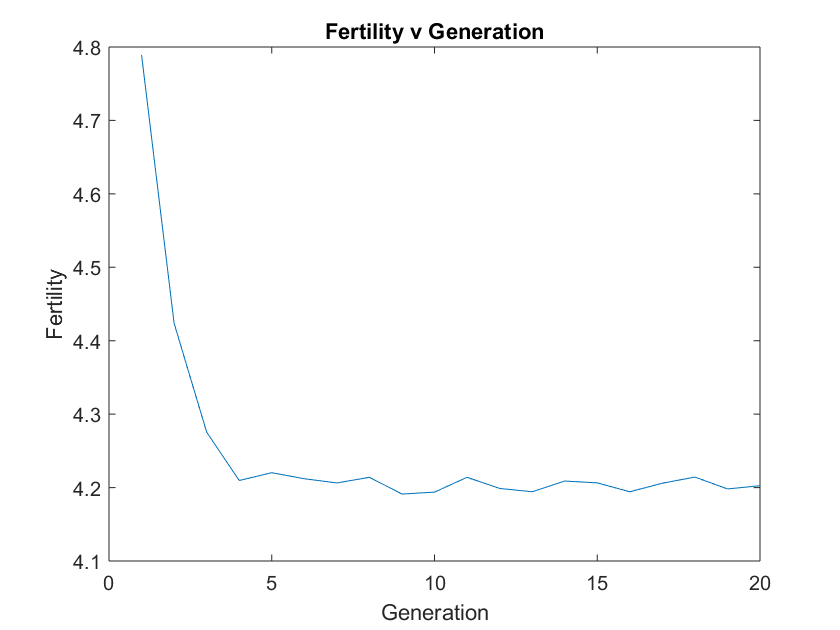

plot([1:1:Gen],FertilityData) 
title('Fertility v Generation')
xlabel('Generation')
ylabel('Fertility')

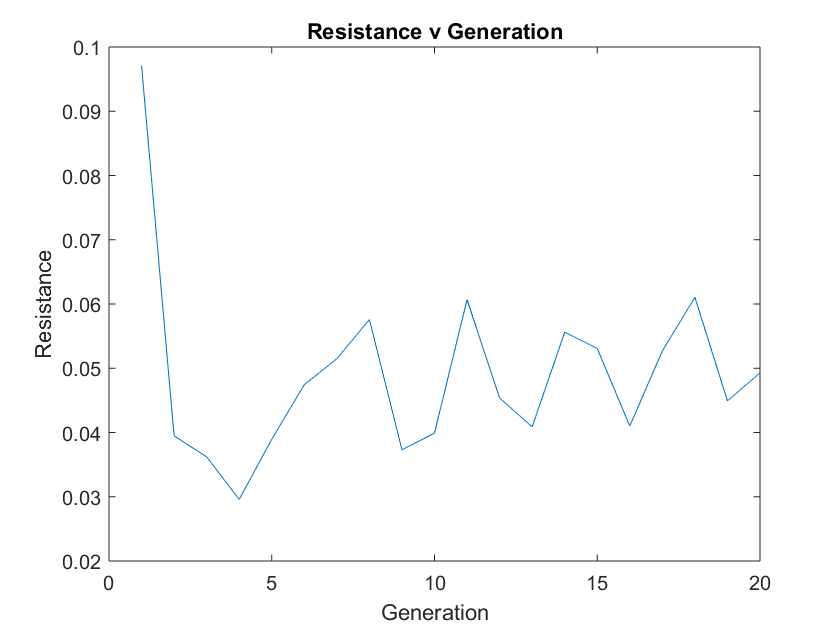

plot([1:1:Gen],ResistanceData) 
title('Resistance v Generation')
xlabel('Generation')
ylabel('Resistance')

toc

Elapsed time is 48.246382 seconds.
